%% Load Parameters
%Inertia: kg*m^2
Ix = 0.014484;
Iy = Ix;
Iz = 0.004026;
Iw = 0.000189;
%Length: m
L = 0.108;
%mass: kg
m = 1.146;
%Moment constant of motor: N*m/A
Kt = 0.0251;
%Resistor: olm
Rm = 0.0464;
%Gravity constant: m/s^2
g = 9.81;

A = [0 0 0 m*g*L/(Iy-Iw) 0             sqrt(6).*Kt.^2/(3*Rm.*(Iy-Iw))  -sqrt(6).*Kt.^2/(3*Rm.*(Iy-Iw)) -sqrt(6).*Kt.^2/(3*Rm.*(Iy-Iw));
     0 0 0 0             m*g*L/(Ix-Iw) 0                               sqrt(2).*Kt.^2/(2*Rm.*(Ix-Iw))  -sqrt(2).*Kt.^2/(2*Rm.*(Ix-Iw));
     0 0 0 0             0             -sqrt(3).*Kt.^2/(3*Rm.*(Iz-Iw)) -sqrt(3).*Kt.^2/(3*Rm.*(Iz-Iw)) -sqrt(3).*Kt.^2/(3*Rm.*(Iz-Iw));
     1 0 0 0             0             0                               0                               0                              ;
     0 1 0 0             0             0                               0                               0                              ;
     0 0 0 0             0             -Kt.^2/(Iw.*Rm)                 0                               0                              ;
     0 0 0 0             0             0                               -Kt.^2/(Iw.*Rm)                 0                              ;
     0 0 0 0             0             0                               0                               -Kt.^2/(Iw.*Rm)                ]

A =          0         0         0   84.9363         0    0.7755   -0.7755   -0.7755
         0         0         0         0   84.9363         0    0.6716   -0.6716
         0         0         0         0         0   -2.0430   -2.0430   -2.0430
    1.0000         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0  -71.8402         0         0
         0         0         0         0         0         0  -71.8402         0
         0         0         0         0         0         0         0  -71.8402


B = [-sqrt(6).*Kt/(3.*Rm.*(Iy-Iw)) sqrt(6).*Kt/(6.*Rm.*(Iy-Iw))    sqrt(6).*Kt/(6.*Rm.*(Iy-Iw)) ;
     0                             -sqrt(2).*Kt/(2.*Rm.*(Ix-Iw))   sqrt(2).*Kt/(2.*Rm.*(Ix-Iw)) ;
     -sqrt(3).*Kt/(3.*Rm.*(Iz-Iw)) -sqrt(3).*Kt/(3.*Rm.*(Iz-Iw))   -sqrt(3).*Kt/(3.*Rm.*(Iz-Iw));
     0                             0                               0                            ;
     0                             0                               0                            ;
     Kt/(Rm.*Iw)                   0                               0                            ;
     0                             Kt/(Rm.*Iw)                     0                            ;
     0                             0                               Kt/(Rm.*Iw)                  ]

B = 	1.0e+03 *

   -0.0309    0.0154    0.0154
         0   -0.0268    0.0268
   -0.0814   -0.0814   -0.0814
         0         0         0
         0         0         0
    2.8622         0         0
         0    2.8622         0
         0         0    2.8622


C = [zeros(5,3) diag(ones(5,1))]

C =      0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1


D=0

D = 0

rank(ctrb(A,B))

ans = 8

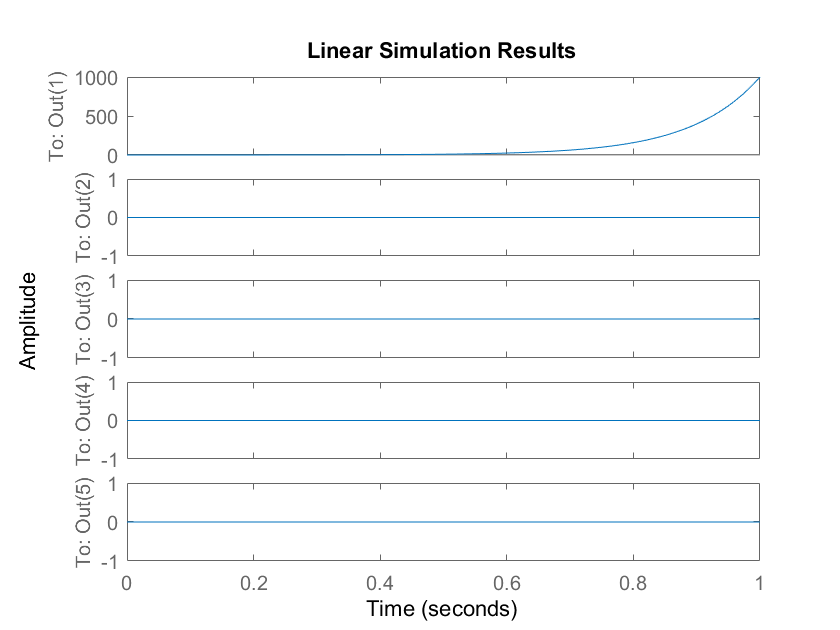

%%Simulation
T = 0:0.01:1;
%U = [zeros(3,length(T))];
%U = [zeros(1,length(T));0.5*ones(1,length(T));-0.5*ones(1,length(T))];
%U = [0.5*ones(1,length(T));-0.25*ones(1,length(T));-0.25*ones(1,length(T))];
%U = [0.25*ones(1,length(T));0.25*ones(1,length(T));0.25*ones(1,length(T))];
U = [zeros(3,length(T))];
x0 = [0 0 0 0.2 0 0 0 0];

sys = ss(A,B,C,D);
lsim(sys,U,T,x0)

Q = diag(ones(1,8));
R = diag(ones(1,3));
[K,S,P] = lqr(sys,Q,R);

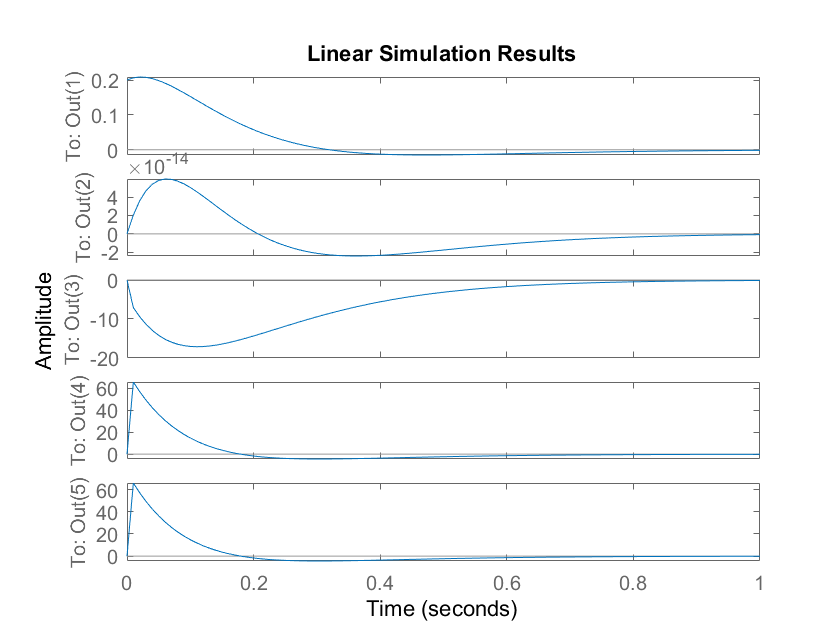

U = [zeros(3,length(T))];
sys2 = ss(A-B*K,B,C,D);
lsim(sys2,U,T,x0)